Raw graph plot:

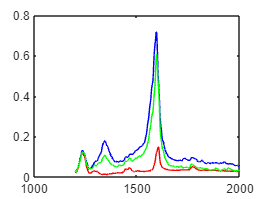

plot(spectra.WavenumberCm1,spectra.x,"k")
hold on 
plot(spectra.WavenumberCm1,spectra.x,"r")
plot(spectra.WavenumberCm1,spectra.x1,"b")
plot(spectra.WavenumberCm1,spectra.x2,"g")
hold off

Baseline correction:

Plot smoothing:

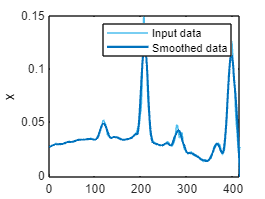

% Smooth input data
x = smoothdata(spectra(:,"x"),"sgolay","SmoothingFactor",0.4);

% Display results
figure
plot(spectra.x,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(x.x,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
ylabel("x")

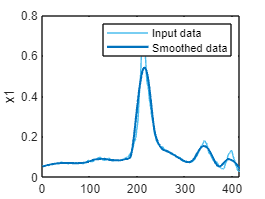

% Smooth input data
x1 = smoothdata(spectra,"sgolay","SmoothingFactor",0.4,...
    "DataVariables","x1");

% Display results
figure
plot(spectra.x1,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(x1.x1,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
ylabel("x1")

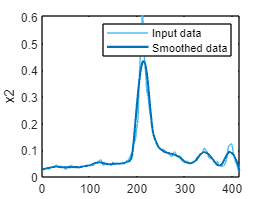

% Smooth input data
x2 = smoothdata(spectra,"sgolay","SmoothingFactor",0.4,...
    "DataVariables","x2");

% Display results
figure
plot(spectra.x2,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(x2.x2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
ylabel("x2")

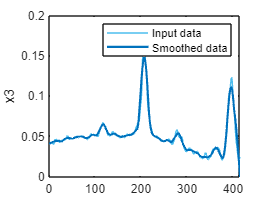

% Smooth input data
x3 = smoothdata(spectra,"sgolay","SmoothingFactor",0.4,...
    "DataVariables","x3");

% Display results
figure
plot(spectra.x3,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(x3.x3,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
ylabel("x3")

 Fourier transform:

xft=fft(spectra.x)

xft =   15.2017 + 0.0000i
  -0.8714 - 0.9791i
   2.6631 + 0.5534i
   0.0092 + 1.3663i
   1.8092 + 1.7534i
  -1.8267 + 0.8835i
   1.1080 + 1.3956i
  -1.5958 + 0.9741i
   0.1952 + 0.6313i
  -1.9148 + 0.3985i


x1ft=fft(spectra.x1)

x1ft =   51.6074 + 0.0000i
 -17.6001 + 4.8013i
  12.3221 - 2.4846i
 -13.2124 + 4.8157i
   9.3831 - 6.3791i
  -6.9781 + 3.6133i
   8.0530 - 1.7821i
  -6.5726 + 6.0259i
   2.6379 - 2.8032i
  -5.3584 + 2.7438i


x2ft=fft(spectra.x2)

x2ft =   35.9277 + 0.0000i
 -13.0640 + 4.6205i
  10.6316 - 1.4020i
  -9.3929 + 4.1325i
   7.8559 - 2.7354i
  -6.6186 + 2.6661i
   6.4579 - 0.7116i
  -5.8881 + 4.0110i
   2.8782 - 1.3335i
  -5.1120 + 1.7703i


x3ft=fft(spectra.x3)

x3ft =   20.8055 + 0.0000i
  -2.0495 - 1.7471i
   2.6971 + 0.0274i
  -0.5406 + 0.9515i
   1.9183 + 1.3102i
  -1.9730 + 0.5341i
   1.1550 + 1.2485i
  -1.7018 + 0.7229i
   0.3225 + 0.5814i
  -1.9521 + 0.1208i



%not sure whether to plot a graph
plot(spectra.WavenumberCm1,xft,"k")

hold on 
plot(spectra.WavenumberCm1,x1ft,"r")

plot(spectra.WavenumberCm1,x2ft,"b")

plot(spectra.WavenumberCm1,x3ft,"g")

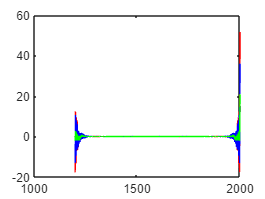

hold off

Noise reduction:

xden=wdenoise(spectra.x)

xden =     0.0267
    0.0265
    0.0261
    0.0262
    0.0264
    0.0267
    0.0270
    0.0272
    0.0274
    0.0276


x1den=wdenoise(spectra.x1)

x1den =     0.0551
    0.0550
    0.0551
    0.0537
    0.0521
    0.0530
    0.0545
    0.0561
    0.0578
    0.0577


x2den=wdenoise(spectra.x2)

x2den =     0.0315
    0.0312
    0.0307
    0.0312
    0.0319
    0.0320
    0.0319
    0.0314
    0.0308
    0.0306


x3den=wdenoise(spectra.x3)

x3den =     0.0400
    0.0404
    0.0410
    0.0416
    0.0422
    0.0420
    0.0416
    0.0403
    0.0390
    0.0393


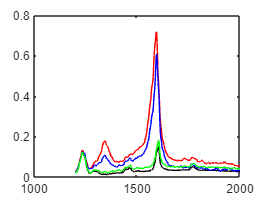


plot(spectra.WavenumberCm1,xden,"k")
hold on 
plot(spectra.WavenumberCm1,x1den,"r")
plot(spectra.WavenumberCm1,x2den,"b")
plot(spectra.WavenumberCm1,x3den,"g")
hold off